clc;
close all;
clear;
load("robot.mat");

#### **Simulate rotating and draw**

homeconfig = homeConfiguration(robot);    % Setting initial angle
test_angle = [-pi/4, 0, 0, 0, 0, 0];
%joint_pos_init = transform_angle(joint_pos_init);;
%deltaconfig = (transform_angle(test_angle))';     % Setting final angle
deltaconfig = test_angle';

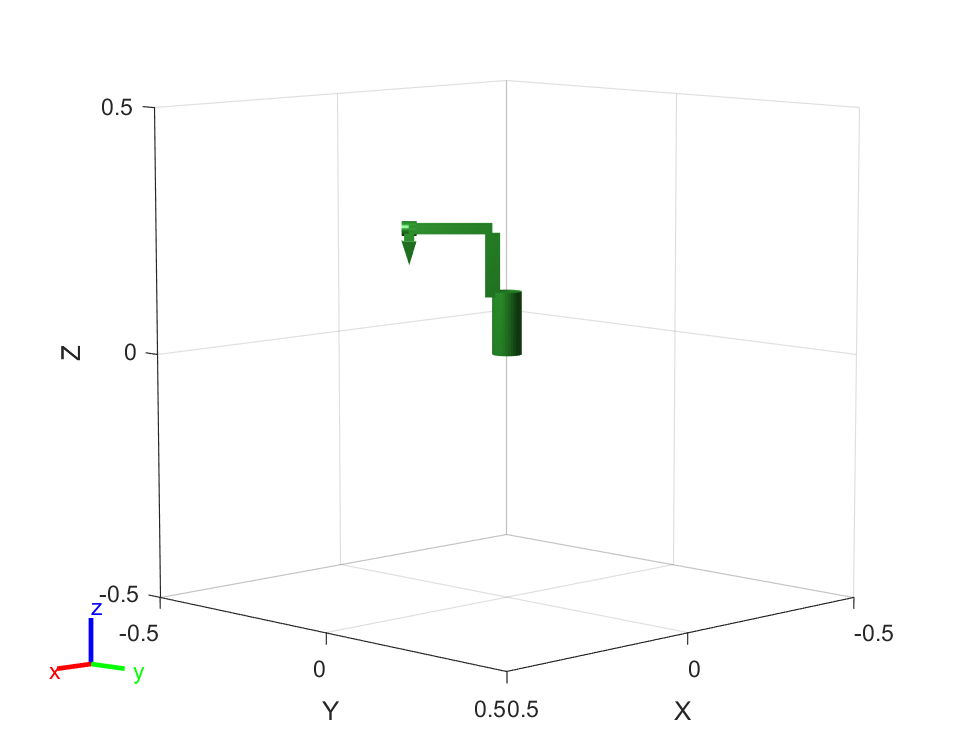

Initial = homeconfig;
Qd = deltaconfig;
Step = 20;
framesPerSecond = 15;
tip_positions = zeros([Step,3]);
for i = 1:Step
    q = Initial + Qd / Step * i;
    tip_positions(i,:) = cal_tip_positions(q);
    show(robot,q,"Collisions","on","Frames","off");
    F(i) = getframe(gcf) ;
    drawnow
end

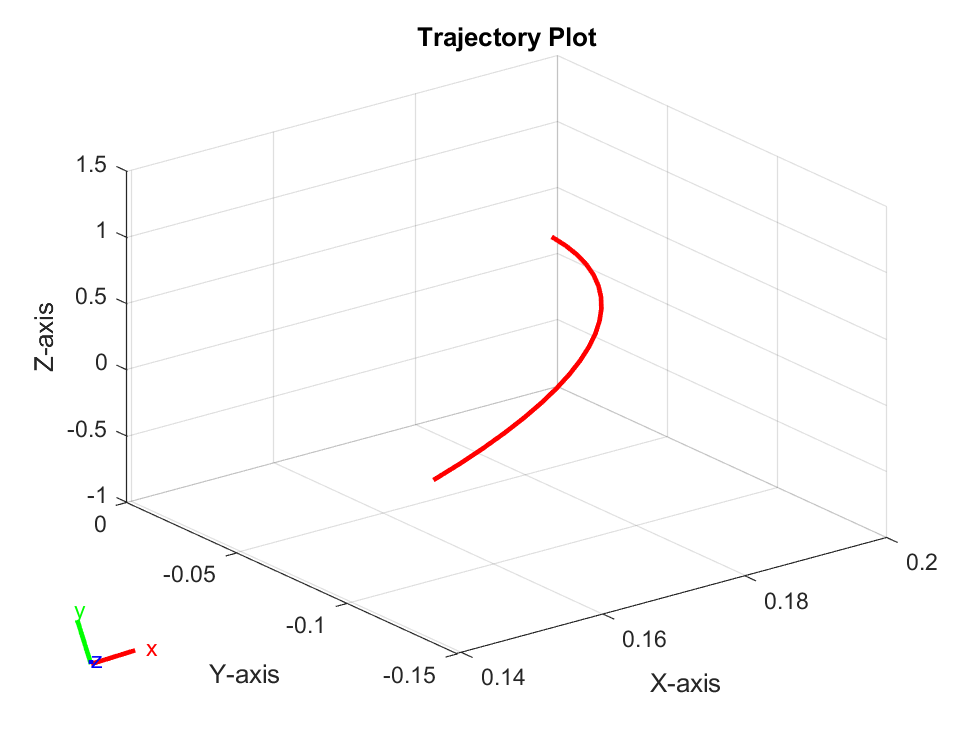


plot3(tip_positions(:, 1),tip_positions(:, 2),tip_positions(:, 3),'r', 'LineWidth', 2);
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('Trajectory Plot');
grid on;

## **Task 2**

initial position: -pi/2 pi/6 -pi/6 -pi/4 0 0 

joint_pos_init = [-pi/2, pi/6, -pi/6, -pi/4, 0, 0];
%joint_pos_init = transform_angle(joint_pos_init);

Intermediate Pose: 0 pi/3 0 0 0 0 

joint_pos_inter = [0, pi/3, 0, 0, 0, 0];
%joint_pos_inter = transform_angle(joint_pos_inter);

Final Pose : pi/4 pi/6 -pi/4 0 0 0 

joint_pos_final = [pi/4, pi/6, -pi/4, 0, 0, 0];
%joint_pos_final = transform_angle(joint_pos_final);

#### angle transform

homeconfig = homeConfiguration(robot);
Initial = homeconfig + joint_pos_init';
Intermediate = homeconfig + joint_pos_inter';
Final = homeconfig + joint_pos_final';

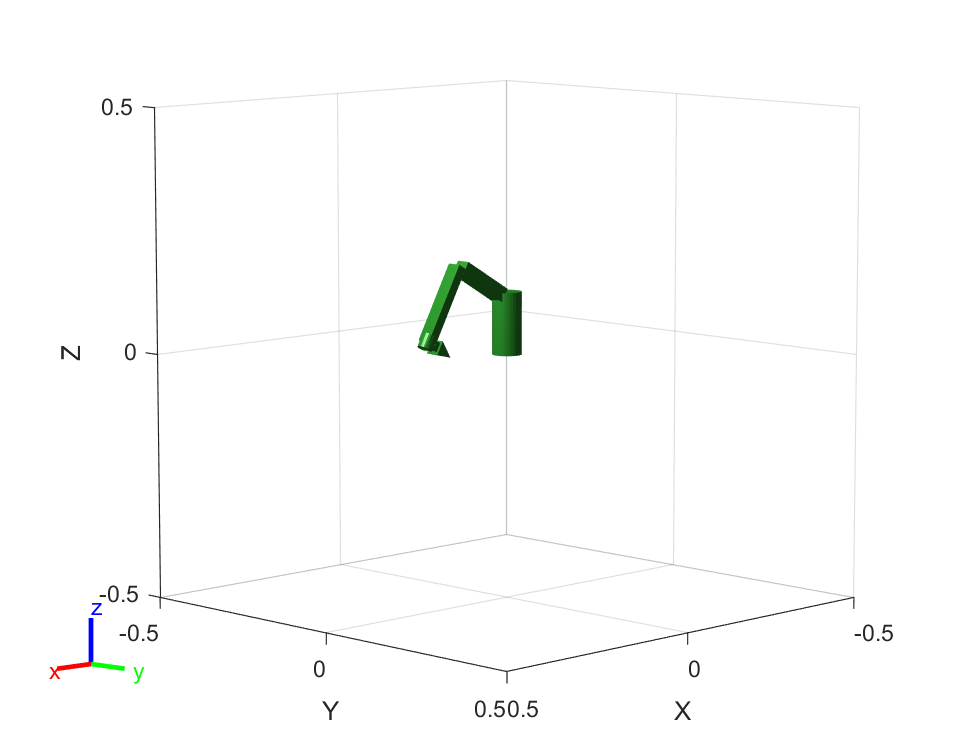

tip_positions = zeros([Step*2,3]);
Qd = Intermediate - Initial; % delta 
Step = 30; %motion duration 
framesPerSecond = 15;
% 
for i = 1:Step
    q = Initial + Qd / Step * i; 
    tip_positions(i,:) = cal_tip_positions(q);
    show(robot,q,"Collisions","on","Frames","off");
    F_1(i) = getframe(gcf);
    drawnow
end

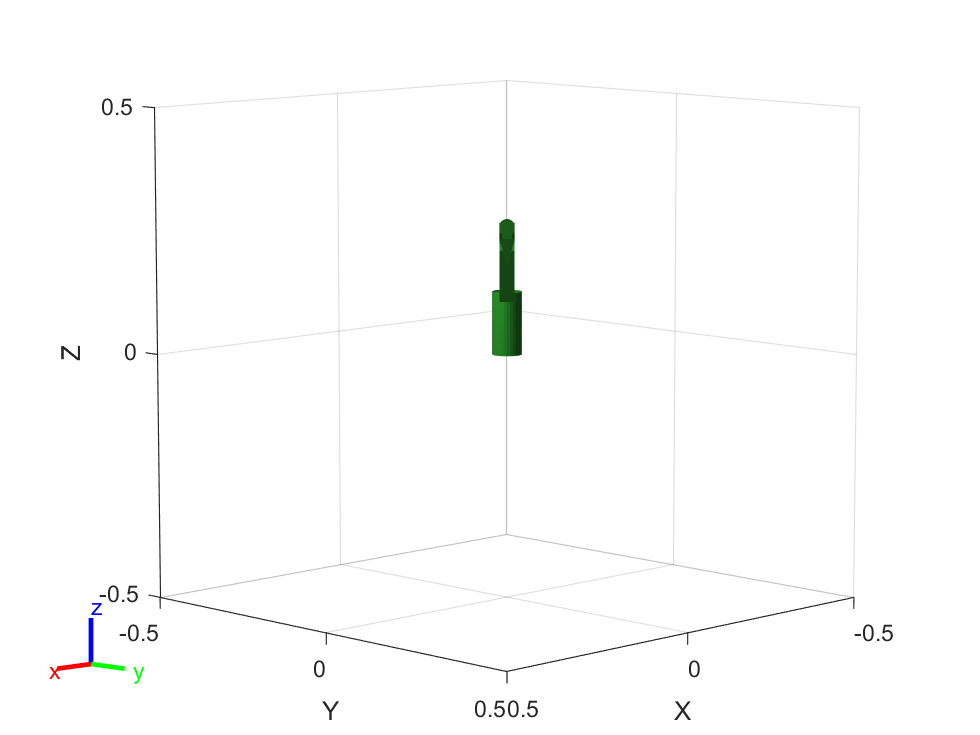

Qd = Final - Intermediate;
for i = 1:Step
    q = Intermediate + Qd / Step * i;
    tip_positions(i+Step,:) = cal_tip_positions(q);
    show(robot,q,"Collisions","on","Frames","off");
    F_2(i) = getframe(gcf) ;
    drawnow
end

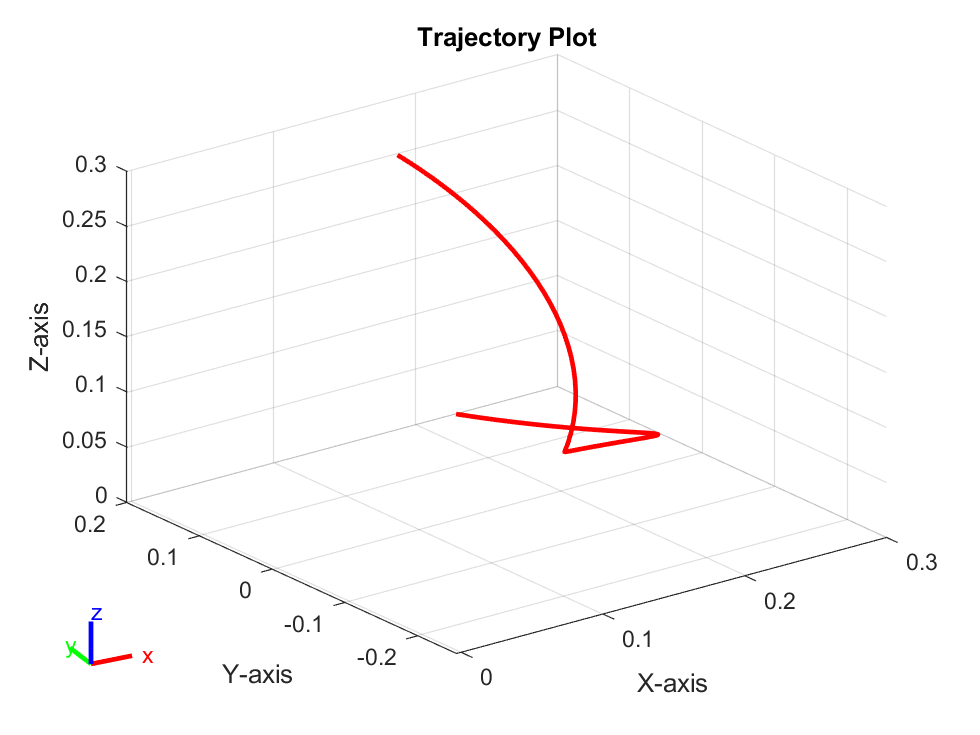

plot3(tip_positions(:, 1),tip_positions(:, 2),tip_positions(:, 3),'r', 'LineWidth', 2);
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('Trajectory Plot');
grid on;


% create the video writer with 1 fps
writerObj = VideoWriter('Task2.avi');
% set the seconds per image
writerObj.FrameRate = 10;
% open the video writer
open(writerObj);
% write the frames to the video _1 
for i=1:length(F_1)
    % convert the image to a frame
    frame = F_1(i) ;    
    writeVideo(writerObj, frame);
end
% write the frames to the video _2
for i=1:length(F_2)
    % convert the image to a frame
    frame = F_2(i) ;    
    writeVideo(writerObj, frame);
end
% close the writer object
close(writerObj);

#### Calculate joint positions and velocities

joint_pos_init; %initial joint position
joint_pos_inter; %inter joint position
joint_pos_final; % final joint position
Step; %motion duration

joint_positions_1 = [];
joint_velocities_1 = [];
for i = 1 : 6
    syms th0 thf a0 a1 a2 a3 th thdot thdotdot t
    th0 = joint_pos_init(i); %initial joint position
    thf = joint_pos_inter(i); %final joint position    
    %Derived expressions of polynomial coefficients
    a0 = th0;
    a1 = 0;
    a2 = 3*(thf-th0)/Step^2;
    a3 = -2*(thf-th0)/Step^3;
    %Substitute back into the cubic polynomial expression
    th = a0 + a1*t + a2*t.^2 + a3*t.^3; %joint position
    thdot = a1 + 2*a2*t + 3*a3*t.^2; %joint velocity
    %thdotdot = diff(th,t,2); %joint acceleration
    %Evaluate symbolic expressions for t
    t = [0:1:Step];
    th = subs(th,t);
    thdot = subs(thdot,t);
    %thdotdot = subs(thdotdot,t);

    %Plot curves
    joint_positions_1 = [joint_positions_1;double(th)];
    joint_velocities_1 = [joint_velocities_1;double(thdot)];   
end

joint_positions_2 = [];
joint_velocities_2 = [];
for i = 1 : 6
    syms th0 thf a0 a1 a2 a3 th thdot thdotdot t
    th0 = joint_pos_inter(i); %initial joint position
    thf = joint_pos_final(i); %final joint position    
    %Derived expressions of polynomial coefficients
    a0 = th0;
    a1 = 0;
    a2 = 3*(thf-th0)/Step^2;
    a3 = -2*(thf-th0)/Step^3;
    %Substitute back into the cubic polynomial expression
    th = a0 + a1*t + a2*t.^2 + a3*t.^3; %joint position
    thdot = a1 + 2*a2*t + 3*a3*t.^2; %joint velocity
    %thdotdot = diff(th,t,2); %joint acceleration
    %Evaluate symbolic expressions for t
    t = [0:1:Step];
    th = subs(th,t);
    thdot = subs(thdot,t);
    %thdotdot = subs(thdotdot,t);

    %Plot curves
    joint_positions_2 = [joint_positions_2;double(th)];
    joint_velocities_2 = [joint_velocities_2;double(thdot)];   
end

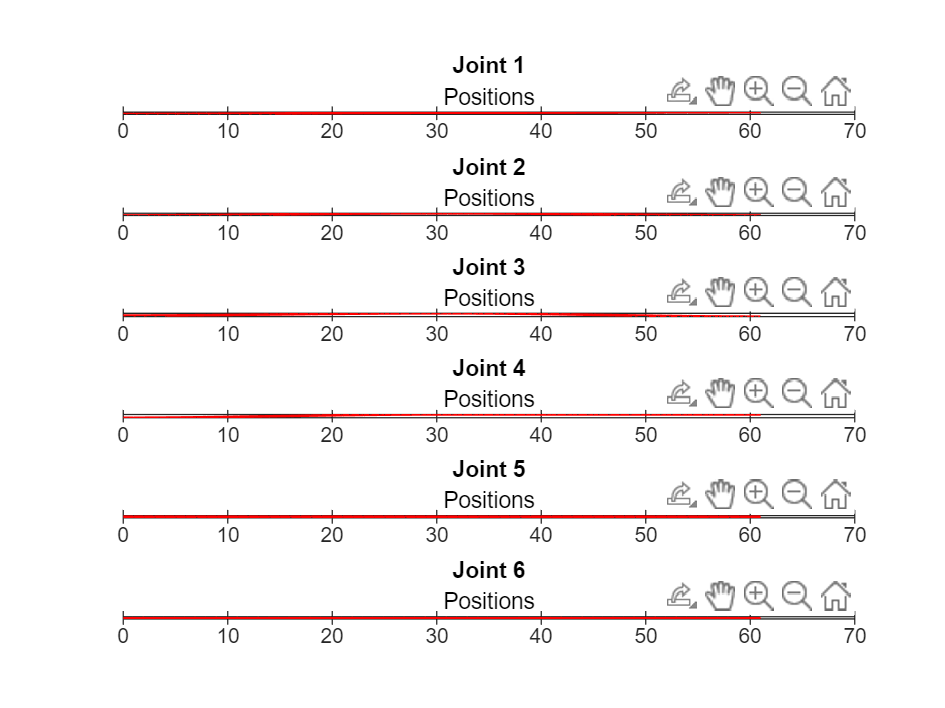

joint_positions = cat(2,joint_positions_1,joint_positions_2);
joint_velocities= cat(2,joint_velocities_1,joint_velocities_2);
t = [0:1:length(joint_positions)-1];
figure;
grid on;
grid minor;
for i = 1:6
    subplot(6, 1, i);
    plot(t,joint_positions(i,:),'Color','r','LineWidth',1);
    title(['Joint ', num2str(i)],"Positions");
end

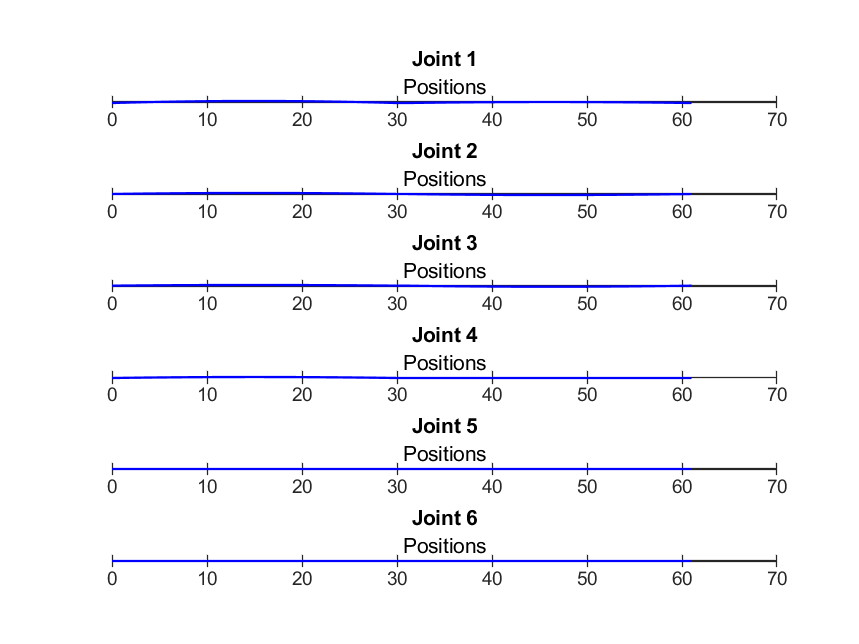


figure;
grid on;
grid minor;
for i = 1:6
    subplot(6, 1, i);
    plot(t,joint_velocities(i,:),'Color','b','LineWidth',1);
    title(['Joint ', num2str(i)],"Velocities");
end

function to calculate transform matrix according to one line of the MDH table

function T = dh_transmatrix(a,alpha,d,theta)
    T = [   cos(theta),             -sin(theta),            0,           a;
            sin(theta)*cos(alpha),  cos(theta)*cos(alpha), -sin(alpha), -sin(alpha)*d;
            sin(theta)*sin(alpha),  cos(theta)*sin(alpha),  cos(alpha),  cos(alpha)*d;
            0,                      0,                      0,           1];
end

function to calculate one tip positions

function tip_position = cal_tip_positions(q)
d1 = 0.128;
a1 = 0.029; 
a2 = 0.108; 
a3 = 0.02; d4 = 0.168;
d6 = -0.02429;
dhparams = [0,   	   0,    	d1,      q(1);
                a1,       -pi/2,    0,        q(2);
                a2,        0,    	0,        q(3);
                a3,       -pi/2,    d4,      q(4);
                0,         pi/2,    0,        q(5);
                0,         pi/2,    d6,     q(6)];



tip_position = zeros([1,3]);
T = eye(4);
for j = 1:size(dhparams,1)
    T = T * dh_transmatrix(dhparams(j,1),dhparams(j,2),dhparams(j,3),dhparams(j,4));
end
for j = 1:3
    tip_position(1,j) = T(j,4);
end
end